%SEGMENTACIÓN DE LOS ROI
close all; 
clear all;
T_ROI=readtable('SVM_buena_calidad_con_glaucoma.csv')

T_ROI = 1230×3 table
          image              Prediccion        glaucoma
    __________________    _________________    ________

    {'image_0001.jpg'}    {'Buena calidad'}       0    
    {'image_0002.jpg'}    {'Buena calidad'}       0    
    {'image_0003.jpg'}    {'Buena calidad'}       0    
    {'image_0004.jpg'}    {'Buena calidad'}       0    
    {'image_0005.jpg'}    {'Buena calidad'}       1    
    {'image_0007.jpg'}    {'Buena calidad'}       0    
    {'image_0008.jpg'}    {'Buena calidad'}       0    
    {'image_0010.jpg'}    {'Buena calidad'}       1    
    {'image_0011.jpg'}    {'Buena calidad'}       0    
    {'image_0012.jpg'}    {'Buena calidad'}       0    
    {'image_0013.jpg'}    {'Buena calidad'}       0    
    {'image_0014.jpg'}    {'Buena calidad'}       0    
    {'image_0015.jpg'}    {'Buena calidad'}       0    
    {'image_0016.jpg'}    {'Buena ca

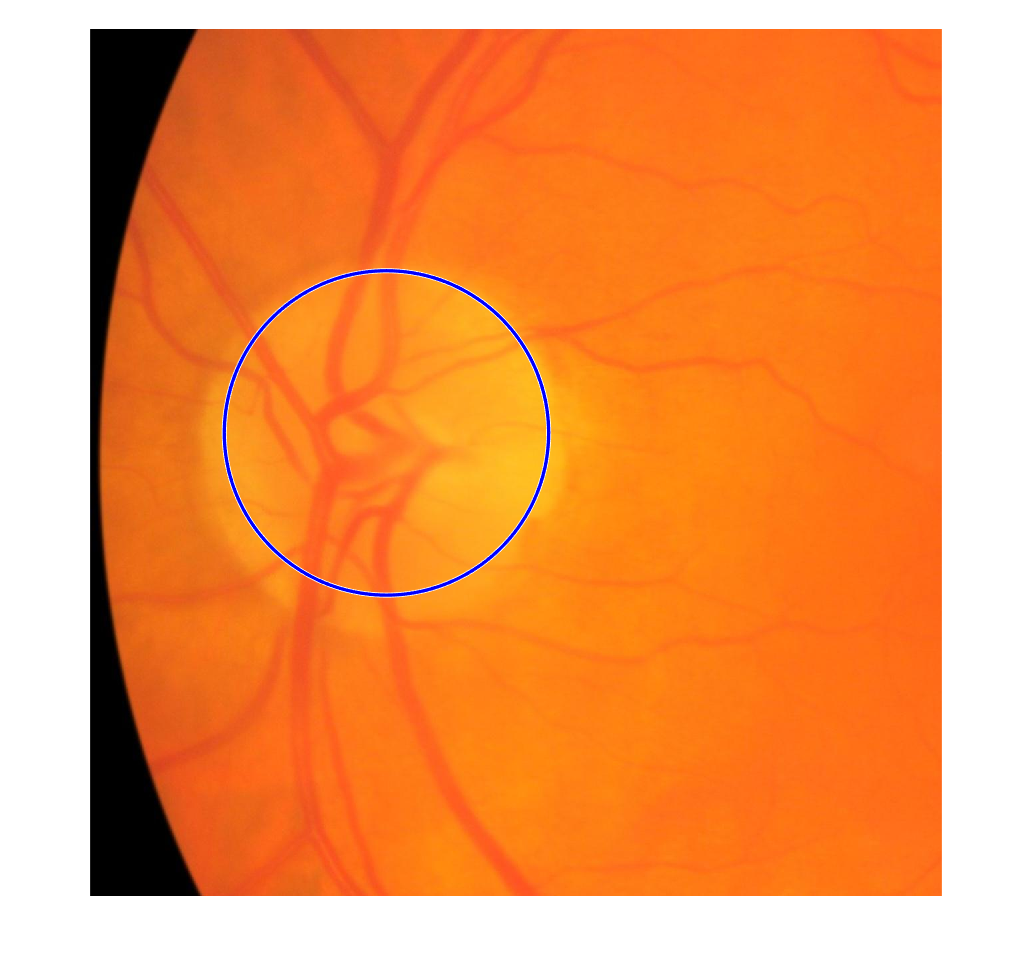

entropia_rojo 1: 3.585388


entropia_verde 1: 6.210812


entropia_azul 1: 4.642006


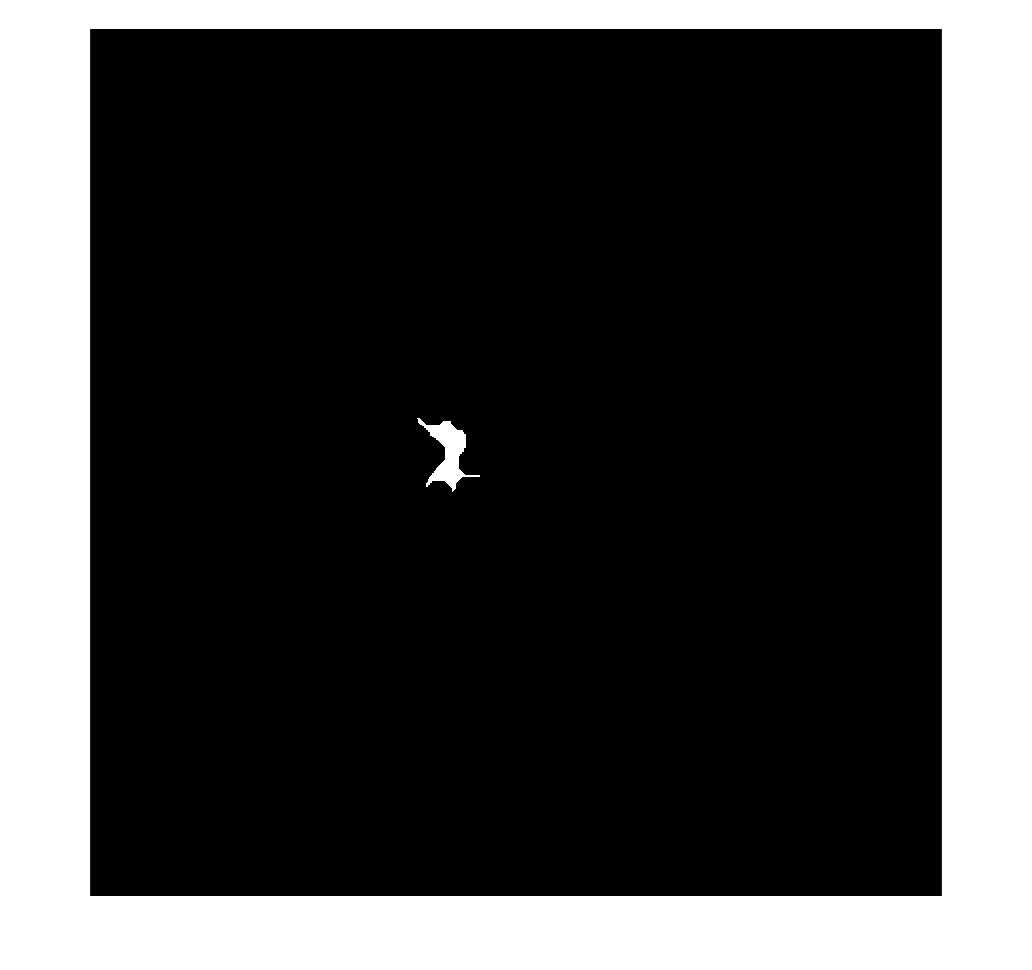

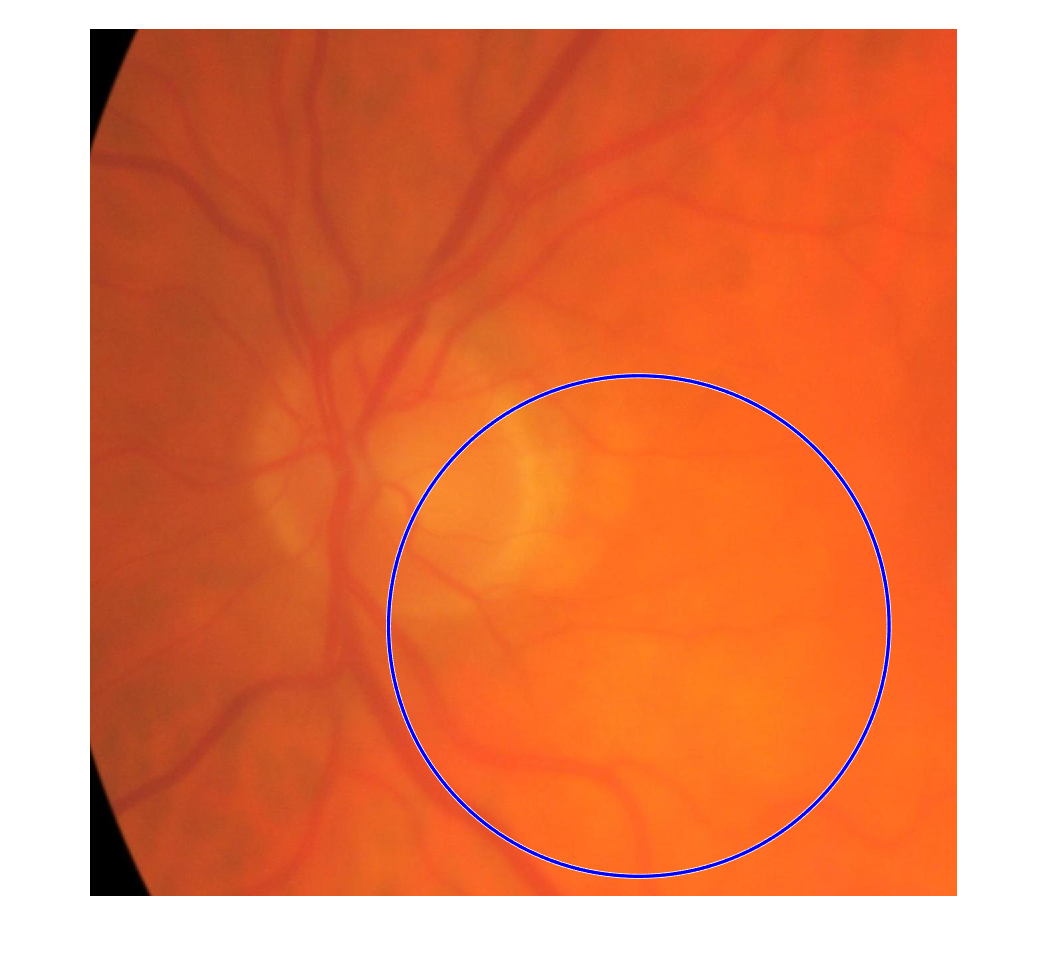

entropia_rojo 2: 5.903522


entropia_verde 2: 6.100232


entropia_azul 2: 3.991873


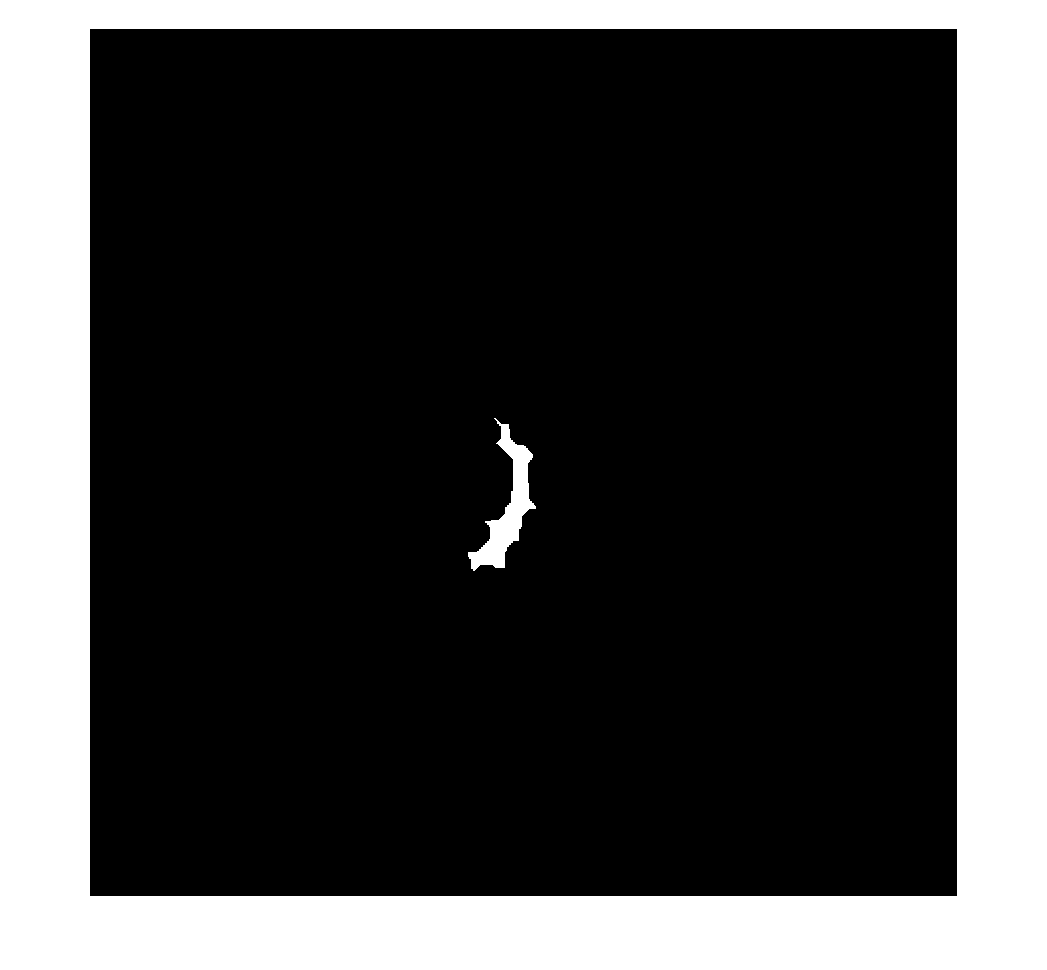


% directorio_origen = 'C:\Users\zabal\OneDrive - Mondragon Unibertsitatea\Escritorio\BIO6\PBL6\MATLAB_Proces_Pred\ROI';
% Carpeta de destino para guardar las imágenes de buena calidad
carpeta_destino = 'C:\Users\zabal\OneDrive - Mondragon Unibertsitatea\Escritorio\BIO6\PBL6\MATLAB_Proces_Pred\SVM_Segmentacion';

% Inicializar vectores para almacenar las entropías
entropias_rojo = zeros(height(T_ROI), 1);
entropias_verde = zeros(height(T_ROI), 1);
entropias_azul = zeros(height(T_ROI), 1);
area_circulo = zeros(height(T_ROI), 1);
mean_A = zeros(height(T_ROI), 1);
std_A = zeros(height(T_ROI), 1);
mean_H = zeros(height(T_ROI), 1);
std_H = zeros(height(T_ROI), 1);
mean_D = zeros(height(T_ROI), 1);
std_D = zeros(height(T_ROI), 1);
mean_V = zeros(height(T_ROI), 1);
std_V = zeros(height(T_ROI), 1);

imagen_combinada_1_names = cell(height(T_ROI), 1);
glaucoma_var = cell(height(T_ROI), 1);
areas_combinaciones = zeros(height(T_ROI), 1);

for i = 1:height(T_ROI)

    nombre_imagen = T_ROI.image{i};

    glaucoma_var{i} = T_ROI.glaucoma(i);

    ROI_origen= imread(T_ROI.image{i});

    % Realizar la descomposición wavelet
    nivel = 3; % Número de niveles de descomposición
    [C,S] = wavedec2(ROI_origen, nivel, 'db1');

    % Extraer coeficientes de detalle y aproximación
    Coefs_A = appcoef2(C, S, 'db1', nivel); % Aproximación
    Coefs_H = detcoef2('h',C,S, nivel);     % Detalle horizontal
    Coefs_V = detcoef2('v',C,S, nivel);     % Detalle vertical
    Coefs_D = detcoef2('d',C,S, nivel);     % Detalle diagonal

    % Calcular estadísticas de los coeficientes de detalle y aproximación
    mean_A(i) = mean(abs(Coefs_A(:)));
    std_A(i) = std(abs(Coefs_A(:)));
    mean_H(i) = mean(abs(Coefs_H(:)));
    std_H(i) = std(abs(Coefs_H(:)));
    mean_V(i) = mean(abs(Coefs_V(:)));
    std_V(i) = std(abs(Coefs_V(:)));
    mean_D(i) = mean(abs(Coefs_D(:)));
    std_D(i) = std(abs(Coefs_D(:)));

    % imshow(ROI_origen)
    canal_rojo= ROI_origen(:,:,1);
    canal_verde= ROI_origen(:,:,2);
    canal_azul= ROI_origen(:,:,3);

    % subplot(5, 3, 1);  imshow(canal_rojo); title('ROI_Canal Rojo');
    % subplot(5, 3, 2);  imshow(canal_verde); title('ROI_Canal Verde');
    % subplot(5, 3, 3);  imshow(canal_azul); title('ROI_Canal Azul');

    entropias_rojo(i) = entropy(canal_rojo);
    entropias_verde(i) = entropy(canal_verde);
    entropias_azul(i) = entropy(canal_azul);

    % fprintf('entropia_rojo %d: %f\n', i, entropias_rojo(i));
    % fprintf('entropia_verde %d: %f\n', i, entropias_verde(i));
    % fprintf('entropia_azul %d: %f\n', i, entropias_azul(i));

    se = strel('disk', 20);
    I_vessels_rojo = imclose(canal_rojo, se);
    I_vessels_verde = imclose(canal_verde, se);
    I_vessels_azul = imclose(canal_azul, se);

    I_sinvenas_rojo=imadjust(I_vessels_rojo); 
    I_sinvenas_verde=imadjust(I_vessels_verde);
    I_sinvenas_azul=imadjust(I_vessels_azul);
    % 
    % subplot(5, 3, 4);  imshow(I_sinvenas_rojo); 
    % subplot(5, 3, 5);  imshow(I_sinvenas_verde); 
    % subplot(5, 3, 6);  imshow(I_sinvenas_azul); 

    sorted_values_rojo = sort(I_sinvenas_rojo(:), 'descend');
    sorted_values_verde = sort(I_sinvenas_verde(:), 'descend');
    sorted_values_azul = sort(I_sinvenas_azul(:), 'descend');

    % Aplicar umbral para seleccionar el % de los píxeles de máxima calidad
    threshold_index_disc_rojo = round(0.03 * numel(sorted_values_rojo));
    threshold_value_disc_rojo = sorted_values_rojo(threshold_index_disc_rojo);
    I_thresholded_disc_rojo_inicial = I_sinvenas_rojo >= threshold_value_disc_rojo;

    threshold_index_disc_verde = round(0.08* numel(sorted_values_verde));
    threshold_value_disc_verde = sorted_values_verde(threshold_index_disc_verde);
    I_thresholded_disc_verde_inicial = I_sinvenas_verde >= threshold_value_disc_verde;

    threshold_index_disc_azul = round(0.03 * numel(sorted_values_azul));
    threshold_value_disc_azul = sorted_values_azul(threshold_index_disc_azul);
    I_thresholded_disc_azul_inicial = I_sinvenas_azul >= threshold_value_disc_azul;

    Disco_corregido_rojo = cell(1, 4);
    Disco_corregido_verde = cell(1, 4);
    Disco_corregido_azul = cell(1, 4);

    Disco_corregido_rojo{1} = I_thresholded_disc_rojo_inicial;
    Disco_corregido_verde{1} = I_thresholded_disc_verde_inicial;
    Disco_corregido_azul{1} = I_thresholded_disc_azul_inicial;

    for j = 1:3
        Disco_corregido_rojo{j+1} = activecontour(I_sinvenas_rojo, Disco_corregido_rojo{j});
        Disco_corregido_verde{j+1} = activecontour(I_sinvenas_verde, Disco_corregido_verde{j});
        Disco_corregido_azul{j+1} = activecontour(I_sinvenas_azul, Disco_corregido_azul{j});
    end


    % Obtener el componente más grande de la imagen binarizada

    resultado_final_rojo = Disco_corregido_rojo{end};
    resultado_final_verde = Disco_corregido_verde{end};
    resultado_final_azul = Disco_corregido_azul{end};
    % 
    % subplot(5, 3, 7);  imshow(I_thresholded_disc_rojo_inicial)
    % subplot(5, 3, 8);  imshow(I_thresholded_disc_verde_inicial)
    % subplot(5, 3, 9);  imshow(I_thresholded_disc_azul_inicial)
    % 
    % subplot(5, 3, 10);  imshow(resultado_final_rojo)
    % subplot(5, 3, 11);  imshow(resultado_final_verde)
    % subplot(5, 3, 12);  imshow(resultado_final_azul)


    if entropias_azul (i)>=4.4

       Disco_corregido_final_azul=resultado_final_azul;

    else 

        Disco_corregido_final_azul= ones(size(canal_azul));

    end 

     if entropias_verde (i)<=6.5

       Disco_corregido_final_verde=resultado_final_verde;

    else 

        Disco_corregido_final_verde= ones(size(canal_verde));

     end

     if entropias_rojo(i)>=7

       Disco_segmentado_final=resultado_final_rojo;

    else 

        Disco_segmentado_final=Disco_corregido_final_azul&resultado_final_rojo&Disco_corregido_final_verde;

    end

    % Disco_segmentado_final=Disco_corregido_final_azul&resultado_final_rojo&Disco_corregido_final_verde;
    figure; 
    % imshow(Disco_corregido_final_azul);


    CC_final = bwconncomp(Disco_segmentado_final);
    numPixels_final = cellfun(@numel, CC_final.PixelIdxList);
    [~, idx_final] = max(numPixels_final);
    Disco_segmentado_final = false(size(Disco_segmentado_final));
    Disco_segmentado_final(CC_final.PixelIdxList{idx_final}) = true;

    figure; 
    % imshow(Disco_segmentado_final)

    figure; 
    se = strel('disk', 20);
    Disco_quitando_alrededor=imerode(Disco_segmentado_final,se);
    % imshow(Disco_quitando_alrededor)

    CC_corregido = bwconncomp(Disco_quitando_alrededor);
    numPixels_corregido = cellfun(@numel, CC_corregido.PixelIdxList);
    [~, idx_corregido] = max(numPixels_corregido);
    Disco_quitando_alrededor = false(size(Disco_quitando_alrededor));
    Disco_quitando_alrededor(CC_corregido.PixelIdxList{idx_corregido}) = true;

    Disco_corregido=imdilate(Disco_quitando_alrededor,se);
    % imshow(Disco_corregido)

    % Encuentra el área del disco segmentado
    area_segmentado = sum(Disco_corregido(:));
    % Calcula el radio de una circunferencia con el mismo área
    radio = sqrt(area_segmentado / pi);

    % Encuentra el centroide del disco segmentado
    stats = regionprops('table', Disco_corregido, 'Centroid');
    centro = stats.Centroid;

    % Dibujar la circunferencia en la imagen original
    hCir = figure;
    imshow(ROI_origen);
    hold on;
    viscircles(centro, radio, 'EdgeColor', 'b', 'LineWidth', 2);
    hold off;
    area_circulo = pi * radio^2;
    frame = getframe(gca);
    imagen_combinada_1 = frame.cdata;


    imshow(ROI_origen);
    hold on;

    % Encontrar contornos de la imagen combinada
    [B, L] = bwboundaries(Disco_corregido, 'noholes');

    % Dibujar cada contorno encontrado
    for k = 1:length(B)
        boundary = B{k};
        fill(boundary(:,2), boundary(:,1), 'r', 'FaceAlpha', 0.5, 'EdgeColor', 'none');
    end
    hold off;

    % Capturar la imagen de la figura actual
    frame_2 = getframe(gca);
    imagen_combinada_2 = frame_2.cdata;
    % 
    nombre_completo = fullfile(carpeta_destino, nombre_imagen);
    imwrite(Disco_corregido, nombre_completo);

    nombre_imagen_2 = sprintf('%s_%d.jpg', nombre_imagen, i); % Crear nombre con índice
    nombre_completo_2 = fullfile(carpeta_destino, nombre_imagen_2);
    imwrite(imagen_combinada_2, nombre_completo_2);

    nombre_imagen_3 = sprintf('%s_%d_%d.jpg', nombre_imagen, i, i); % Crear nombre con índice
    nombre_completo_2 = fullfile(carpeta_destino, nombre_imagen_3);
    imwrite(imagen_combinada_1, nombre_completo_2);

    imagen_combinada_1_names{i} = nombre_imagen_3;

                    %SEGMENTACIÓN DEL CUP
                
                     nombre_imagen = T_ROI.image{i};

                    ROI_origen= imread(T_ROI.image{i});
                    % imshow(ROI_origen)
                    canal_rojo= ROI_origen(:,:,1);
                    canal_verde= ROI_origen(:,:,2);
                    canal_azul= ROI_origen(:,:,3);

                    % subplot(5, 3, 1);  imshow(canal_rojo); title('ROI_Canal Rojo');
                    % subplot(5, 3, 2);  imshow(canal_verde); title('ROI_Canal Verde');
                    % subplot(5, 3, 3);  imshow(canal_azul); title('ROI_Canal Azul');

                    entropias_rojo(i) = entropy(canal_rojo);
                    entropias_verde(i) = entropy(canal_verde);
                    entropias_azul(i) = entropy(canal_azul);

                    fprintf('entropia_rojo %d: %f\n', i, entropias_rojo(i));
                    fprintf('entropia_verde %d: %f\n', i, entropias_verde(i));
                    fprintf('entropia_azul %d: %f\n', i, entropias_azul(i));

                    se = strel('disk', 20);
                    I_vessels_rojo = imclose(canal_rojo, se);
                    I_vessels_verde = imclose(canal_verde, se);
                    I_vessels_azul = imclose(canal_azul, se);

                    I_sinvenas_rojo=imadjust(I_vessels_rojo); 
                    I_sinvenas_verde=imadjust(I_vessels_verde);
                    I_sinvenas_azul=imadjust(I_vessels_azul);
                    % 
                    % subplot(5, 3, 4);  imshow(I_sinvenas_rojo); 
                    % subplot(5, 3, 5);  imshow(I_sinvenas_verde); 
                    % subplot(5, 3, 6);  imshow(I_sinvenas_azul); 

                    sorted_values_rojo = sort(I_sinvenas_rojo(:), 'descend');
                    sorted_values_verde = sort(I_sinvenas_verde(:), 'descend');
                    sorted_values_azul = sort(I_sinvenas_azul(:), 'descend');

                    % Aplicar umbral para seleccionar el % de los píxeles de máxima calidad
                    threshold_index_cup_rojo = round(0.01 * numel(sorted_values_rojo));
                    threshold_value_cup_rojo = sorted_values_rojo(threshold_index_cup_rojo);
                    I_thresholded_cup_rojo_inicial = I_sinvenas_rojo >= threshold_value_cup_rojo;

                    threshold_index_cup_verde = round(0.03* numel(sorted_values_verde));
                    threshold_value_cup_verde = sorted_values_verde(threshold_index_cup_verde);
                    I_thresholded_cup_verde_inicial = I_sinvenas_verde >= threshold_value_cup_verde;

                    threshold_index_cup_azul = round(0.01 * numel(sorted_values_azul));
                    threshold_value_cup_azul = sorted_values_azul(threshold_index_cup_azul);
                    I_thresholded_cup_azul_inicial = I_sinvenas_azul >= threshold_value_cup_azul;

                    
                    if entropias_azul (i)>=4.4 

                       Cup_corregido_final_azul=I_thresholded_cup_azul_inicial;

                    else 

                        Cup_corregido_final_azul= ones(size(canal_azul));

                    end 

                    Cup_segmentado_final=I_thresholded_cup_azul_inicial&I_thresholded_cup_verde_inicial;

                    if any(Cup_segmentado_final(:))
                        % Encuentra y selecciona el contorno con más píxeles
                        CC_Cup_final = bwconncomp(Cup_segmentado_final);
                        numPixels_final = cellfun(@numel, CC_Cup_final.PixelIdxList);
                        [~, idx_final_cup] = max(numPixels_final);
                        Cup_segmentado_final = false(size(Cup_segmentado_final));
                        Cup_segmentado_final(CC_Cup_final.PixelIdxList{idx_final_cup}) = true;
                    end

                    figure; 
                    imshow(Cup_segmentado_final);

                    if any(Cup_segmentado_final(:))
                        imagen_anillo_final = Disco_corregido & ~Cup_segmentado_final;
                        % imshow(imagen_anillo_final); 
                        stats = regionprops('table', imagen_anillo_final, 'Area');
                        area_zona_blanca = sum(stats.Area);
                        areas_combinaciones(i) = area_zona_blanca;
                    end 

                    CupHFig = figure;  
                    title('ROI Combinada (AND)');
                    imshow(ROI_origen);
                    hold on;

                    % Encontrar contornos de la imagen combinada
                    [B, L] = bwboundaries(Cup_segmentado_final, 'noholes');

                    % Dibujar cada contorno encontrado
                    for k = 1:length(B)
                        boundary = B{k};
                        fill(boundary(:,2), boundary(:,1), 'r', 'FaceAlpha', 0.5, 'EdgeColor', 'none');
                    end
                    hold off;

                    frame_3 = getframe(gca);
                    imagen_combinada_cup = frame_3.cdata;

                    nombre_imagen_2 = sprintf('%s_%d_CUP.jpg', nombre_imagen, i); % Crear nombre con índice
                    nombre_completo_2 = fullfile(carpeta_destino, nombre_imagen_2);
                    imwrite(imagen_combinada_cup, nombre_completo_2);
end


T_output = table(imagen_combinada_1_names, glaucoma_var, areas_combinaciones,entropias_rojo,entropias_verde,entropias_azul,area_circulo, mean_A,std_A,mean_H,std_H,mean_D,std_D,mean_V,std_V, 'VariableNames', {'image', 'Glaucoma', 'Area','Entropia_CR','Entropia_CV','Entropia_CA','Area_Disco', 'mean_A','std_A','mean_H','std_H','mean_D','std_D','mean_V','std_V'});

output_filename = fullfile(carpeta_destino, 'Resultado_ROI_SVM_Glaucoma.csv');
writetable(T_output, output_filename);